%第一次作业习题2
clc, clear, close all;


%a为月份，b为月份对应的销量
a=[1, 2, 3, 4, 5, 6, 7, 8, 9, 10,11,12]

a =      1     2     3     4     5     6     7     8     9    10    11    12


b=[2056,2395,2600,2298,1634,1600,1873,1478,1900,1500,2046,1556];
%销量值预处理
b_max=max(b);
b_min=min(b);
b=(b-b_min)/(b_max-b_min)

b =     0.5152    0.8173    1.0000    0.7308    0.1390    0.1087    0.3520         0    0.3761    0.0196    0.5062    0.0695


%取六个数据作为样本点来训练，剩下三个来验证

%拟合
%样本属性值
input=zeros(3,6);
input(1,:)=b(1:6);
input(2,:)=b(2:7);
input(3,:)=b(3:8);
input

input =     0.5152    0.8173    1.0000    0.7308    0.1390    0.1087
    0.8173    1.0000    0.7308    0.1390    0.1087    0.3520
    1.0000    0.7308    0.1390    0.1087    0.3520         0



%样本目标标签值
target=b(4:9)

target =     0.7308    0.1390    0.1087    0.3520         0    0.3761



%测试部分
test=zeros(3,3);
test(1,:)=b(7:9);
test(2,:)=b(8:10);
test(3,:)=b(9:11);

test_target=b(10:12);


% 创建网络
tranFcn = 'traingd'; % 选择训练函数（学习规则）
hiddenLayerSize = 5; % 隐含层神经元的数目
net = feedforwardnet(hiddenLayerSize,tranFcn);



% 网络参数设置
net.layers{1}.transferFcn = 'tansig'; % 隐含层的激活函数
net.layers{2}.transferFcn = 'logsig'; % 输出层的激活函数
 net.trainparam.show = 500; % 每次循环50次
net.trainParam.epochs = 15000; % 最大循环500次
net.trainparam.goal = 0.001; % 期望目标误差最小值


% 初始网络预测
%Configure：配置网络输入和输出,以达到最好的匹配输入和目标数据
net = configure(net,input,target);
pred1 = net(input)

pred1 =     0.7126    0.5290    0.4898    0.7067    0.7273    0.7207


%pred1为所对应的input的初始网络预测值


% 训练网络并预测
net = train(net, input, target);
pred2 = net(input)

pred2 =     0.6699    0.3895    0.3883    0.4377    0.3805    0.3755


%pred2为所对应的input的训练后网络预测值

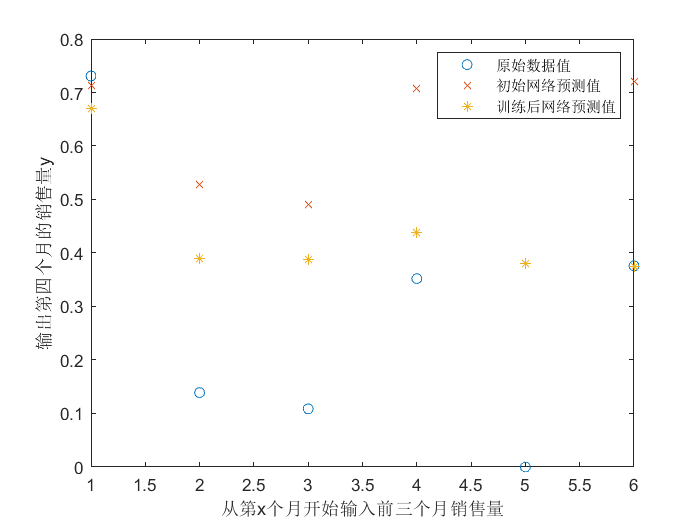


% 绘图
plot(a(1:6), target, 'o', a(1:6), pred1, 'x', a(1:6), pred2, '*')
legend('原始数据值','初始网络预测值','训练后网络预测值')
xlabel '从第x个月开始输入前三个月销售量'   
ylabel '输出第四个月的销售量y'


save('net2.mat','net');       % 将网络net2保存为.mat文件，后面可直接调用


load('net2.mat');     % 导入之前保存的网络
%预测函数
fprintf('请输入测试数据x');

请输入测试数据x


fprintf('输出测试结果y');

输出测试结果y

y=sim(net,test)

y =     0.3985    0.3763    0.4375


test_target

test_target =     0.0196    0.5062    0.0695


Error=y-test_target

Error =     0.3788   -0.1300    0.3680
